load('C:\Users\mrsco\Box\DataAndAnalysis\labData\OKR\batch\cellList_OKR.mat')
%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar_Speed_VarWidth'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {''}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Excitation', '_PDND'};
mustHave_2b = {'Inhibition', '_PDND'};
cantHave_1 = [];
cantHave_2 = {'Extracellular'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

speeds = [2.5, 5, 10, 20, 30, 40];
peaksPD_ex = zeros(0, numel(speeds));
peaksND_ex = zeros(0, numel(speeds));
chargesPD_ex = zeros(0, numel(speeds));
chargesND_ex = zeros(0, numel(speeds));
useOnlyDSCells = 0;
cellType = []; %tracks index of UP and DOWN cells. A 1 means its an up cell. A zero means its a down cell
coordinates=[];
cells = {};
for i = 1:size(cellList, 1)
    struct_i = cellList{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    tags = struct_i.Tags;
    PDFound = 0;
    isUp = 0;
    isDown = 0;
    for j = 1:numel(tags)
        switch tags{j}
            case 'UP Cell'
                isUp = 1;
                PDFound = 1;
                break
            case 'DOWN Cell'
                isDown = 1;
                PDFound = 1;
                break
        end
    end
    
    if ~isUp && ~isDown && useOnlyDSCells
        continue
    end
    cells{end + 1} = struct_i.cellID;
    [coordinates_x, coordinates_y] = pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
    coordinates = [coordinates; -coordinates_x, coordinates_y];
    
    combos_i = loc.Analysis_Results.speedAndOrientationCombos;
    peak90_ex = loc.Analysis_Results.mean_PeakByComboIndex(combos_i(1, :) == 90);
    peak270_ex = loc.Analysis_Results.mean_PeakByComboIndex(combos_i(1, :) == 270);
    charge90_ex = loc.Analysis_Results.mean_ChargeByComboIndex(combos_i(1, :) == 90);
    charge270_ex = loc.Analysis_Results.mean_ChargeByComboIndex(combos_i(1, :) == 270);
    %in the case where you're looking at more than just cells that were
    %clearly up or down cells, decide what to call the preferred and null
    %direction of this cell
    if ~isUp && ~isDown
        numNinetyGreater = peak90_ex > peak270_ex;
        if numNinetyGreater > size(ninetyDegResponses, 2)/2
            isUp = 1;
        elseif numNinetyGreater < size(ninetyDegResponses, 2)/2
            isDown = 1;
        else %if equal
            if mean(ninetyDegResponses) > mean(peak270_ex)
                isUp = 1;
            else
                isDown = 1;
            end
        end
    end
    
    if isUp
        peaksPD_ex = [peaksPD_ex; peak90_ex];
        peaksND_ex = [peaksND_ex; peak270_ex];
        chargesPD_ex = [chargesPD_ex; charge90_ex];
        chargesND_ex = [chargesND_ex; charge270_ex];
        cellType(end + 1) = 1;
    elseif isDown
        peaksPD_ex = [peaksPD_ex; peak270_ex];
        peaksND_ex = [peaksND_ex; peak90_ex];
        chargesPD_ex = [chargesPD_ex; charge270_ex];
        chargesND_ex = [chargesND_ex; charge90_ex];
        cellType(end + 1) = 0;
    end
end

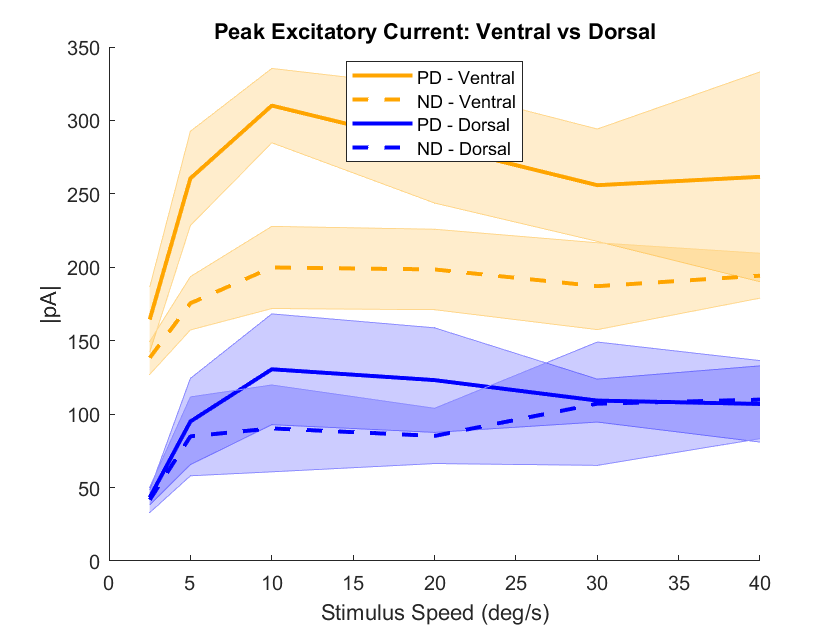

speedIndex_F = @(a, b) (a-b)./(a+b);

ventralIndices = coordinates(:, 2) < 0;
dorsalIndices = coordinates(:, 2) > 0;
nasalIndices = coordinates(:, 1) < 0;
temporalIndices = coordinates(:, 1) > 0;

SE_F = @(m) std(m)/sqrt(size(m, 1));

%plot speed tuning of ventral vs dorsal cells
figure
title('Peak Excitatory Current: Ventral vs Dorsal')
hold on
shadedErrorBar(speeds, mean(peaksPD_ex(ventralIndices, :)), SE_F(peaksPD_ex(ventralIndices, :)),'lineprops', {'Color', [255, 165, 0]/255, 'LineWidth', 2})
shadedErrorBar(speeds, mean(peaksND_ex(ventralIndices, :)), SE_F(peaksND_ex(ventralIndices, :)), 'lineprops', {'Color', [255, 165, 0]/255, 'LineWidth', 2, 'LineStyle', '--'})
shadedErrorBar(speeds, mean(peaksPD_ex(dorsalIndices, :)), SE_F(peaksPD_ex(dorsalIndices, :)), 'lineprops', {'Color', [0, 0, 255]/255, 'LineWidth', 2})
shadedErrorBar(speeds, mean(peaksND_ex(dorsalIndices, :)), SE_F(peaksND_ex(dorsalIndices, :)), 'lineprops', {'Color', [0, 0, 255]/255, 'LineWidth', 2, 'LineStyle', '--'})
xlabel('Stimulus Speed (deg/s)')
ylabel('|pA|')
lgd = legend('PD - Ventral', 'ND - Ventral', 'PD - Dorsal', 'ND - Dorsal');
lgd.Location = 'best';

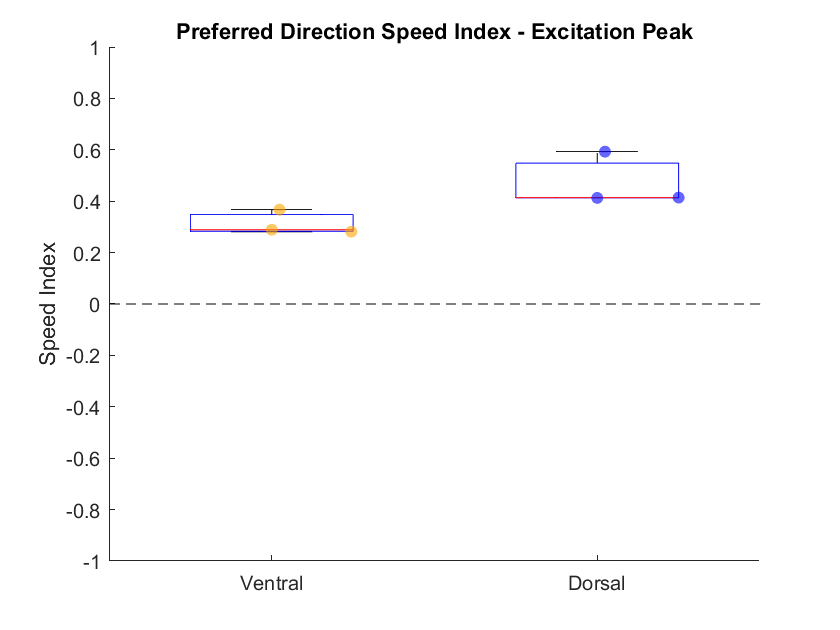

speedIndex_peak = speedIndex_F(peaksPD_ex(:, 3), peaksPD_ex(:, 1));

speedIndexPD_ventral = speedIndex_peak(ventralIndices);
speedIndexPD_dorsal = speedIndex_peak(dorsalIndices);

allPoints = [speedIndexPD_ventral; speedIndexPD_dorsal];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(speedIndexPD_ventral); 
groupIDs(indx1 + 1:end) = 1;

figure
title ('Preferred Direction Speed Index - Excitation Peak')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(speedIndexPD_ventral)), speedIndexPD_ventral,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(speedIndexPD_dorsal))+1, speedIndexPD_dorsal,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
plot([0 3], [0 0], '--k')
xticklabels({'Ventral', 'Dorsal'})
ylabel('Speed Index')
box off
ylim([-1 1])

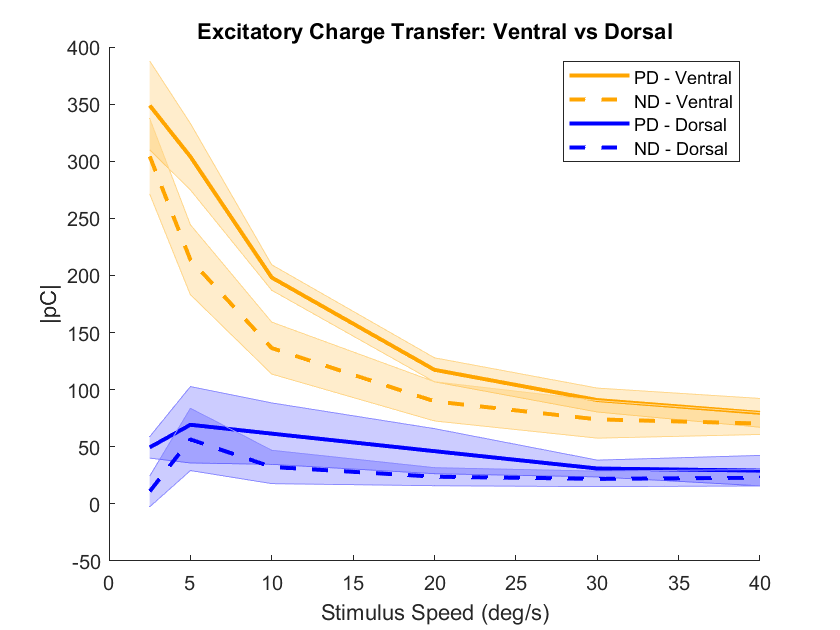


figure
title('Excitatory Charge Transfer: Ventral vs Dorsal')
hold on
shadedErrorBar(speeds, mean(chargesPD_ex(ventralIndices, :)), SE_F(chargesPD_ex(ventralIndices, :)),'lineprops', {'Color', [255, 165, 0]/255, 'LineWidth', 2})
shadedErrorBar(speeds, mean(chargesND_ex(ventralIndices, :)), SE_F(chargesND_ex(ventralIndices, :)), 'lineprops', {'Color', [255, 165, 0]/255, 'LineWidth', 2, 'LineStyle', '--'})
shadedErrorBar(speeds, mean(chargesPD_ex(dorsalIndices, :)), SE_F(chargesPD_ex(dorsalIndices, :)), 'lineprops', {'Color', [0, 0, 255]/255, 'LineWidth', 2})
shadedErrorBar(speeds, mean(chargesND_ex(dorsalIndices, :)), SE_F(chargesND_ex(dorsalIndices, :)), 'lineprops', {'Color', [0, 0, 255]/255, 'LineWidth', 2, 'LineStyle', '--'})
xlabel('Stimulus Speed (deg/s)')
ylabel('|pC|')
lgd = legend('PD - Ventral', 'ND - Ventral', 'PD - Dorsal', 'ND - Dorsal');
lgd.Location = 'best';

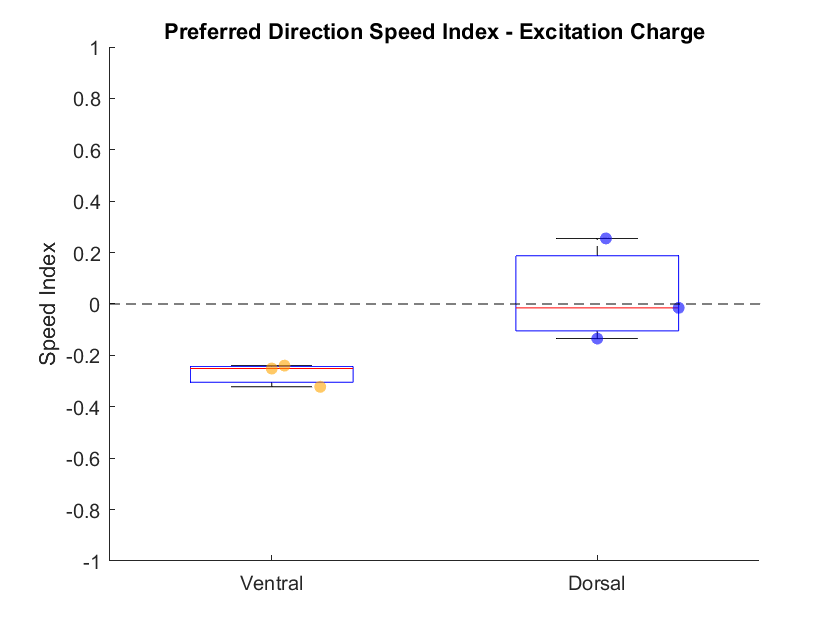

speedIndex_charge = speedIndex_F(chargesPD_ex(:, 3), chargesPD_ex(:, 1));

speedIndexPD_ventral = speedIndex_charge(ventralIndices);
speedIndexPD_dorsal = speedIndex_charge(dorsalIndices);

allPoints = [speedIndexPD_ventral; speedIndexPD_dorsal];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(speedIndexPD_ventral); 
groupIDs(indx1 + 1:end) = 1;

figure
title ('Preferred Direction Speed Index - Excitation Charge')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(speedIndexPD_ventral)), speedIndexPD_ventral,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(speedIndexPD_dorsal))+1, speedIndexPD_dorsal,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
plot([0 3], [0 0], '--k')
xticklabels({'Ventral', 'Dorsal'})
ylabel('Speed Index')
box off
ylim([-1 1])

## repeat for inhibition

peaksPD_inh = zeros(0, numel(speeds));
peaksND_inh = zeros(0, numel(speeds));
chargesPD_inh = zeros(0, numel(speeds));
chargesND_inh = zeros(0, numel(speeds));
useOnlyDSCells = 0;
cellType = []; %tracks index of UP and DOWN cells. A 1 means its an up cell. A zero means its a down cell
coordinates=[];
cells = {};
for i = 1:size(cellList, 1)
    struct_i = cellList{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    tags = struct_i.Tags;
    PDFound = 0;
    isUp = 0;
    isDown = 0;
    for j = 1:numel(tags)
        switch tags{j}
            case 'UP Cell'
                isUp = 1;
                PDFound = 1;
                break
            case 'DOWN Cell'
                isDown = 1;
                PDFound = 1;
                break
        end
    end
    
    if ~isUp && ~isDown && useOnlyDSCells
        continue
    end
    cells{end + 1} = struct_i.cellID;
    [coordinates_x, coordinates_y] = pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
    coordinates = [coordinates; -coordinates_x, coordinates_y];
    
    combos_i = loc.Analysis_Results.speedAndOrientationCombos;
    peak90_inh = loc.Analysis_Results.mean_PeakByComboIndex(combos_i(1, :) == 90);
    peak270_inh = loc.Analysis_Results.mean_PeakByComboIndex(combos_i(1, :) == 270);
    charge90_inh = loc.Analysis_Results.mean_ChargeByComboIndex(combos_i(1, :) == 90);
    charge270_inh = loc.Analysis_Results.mean_ChargeByComboIndex(combos_i(1, :) == 270);
    %in the case where you're looking at more than just cells that were
    %clearly up or down cells, decide what to call the preferred and null
    %direction of this cell
    if ~isUp && ~isDown
        numNinetyGreater = peak90_inh > peak270_inh;
        if numNinetyGreater > size(ninetyDegResponses, 2)/2
            isUp = 1;
        elseif numNinetyGreater < size(ninetyDegResponses, 2)/2
            isDown = 1;
        else %if equal
            if mean(ninetyDegResponses) > mean(peak270_inh)
                isUp = 1;
            else
                isDown = 1;
            end
        end
    end
    
    if isUp
        peaksPD_inh = [peaksPD_inh; peak90_inh];
        peaksND_inh = [peaksND_inh; peak270_inh];
        chargesPD_inh = [chargesPD_inh; charge90_inh];
        chargesND_inh = [chargesND_inh; charge270_inh];
        cellType(end + 1) = 1;
    elseif isDown
        peaksPD_inh = [peaksPD_inh; peak270_inh];
        peaksND_inh = [peaksND_inh; peak90_inh];
        chargesPD_inh = [chargesPD_inh; charge270_inh];
        chargesND_inh = [chargesND_inh; charge90_inh];
        cellType(end + 1) = 0;
    end
end

chargesPD_inh(chargesPD_inh<0) = 0; %get rid of negatives if they exist... they mess everything up
chargesND_inh(chargesND_inh<0) = 0;

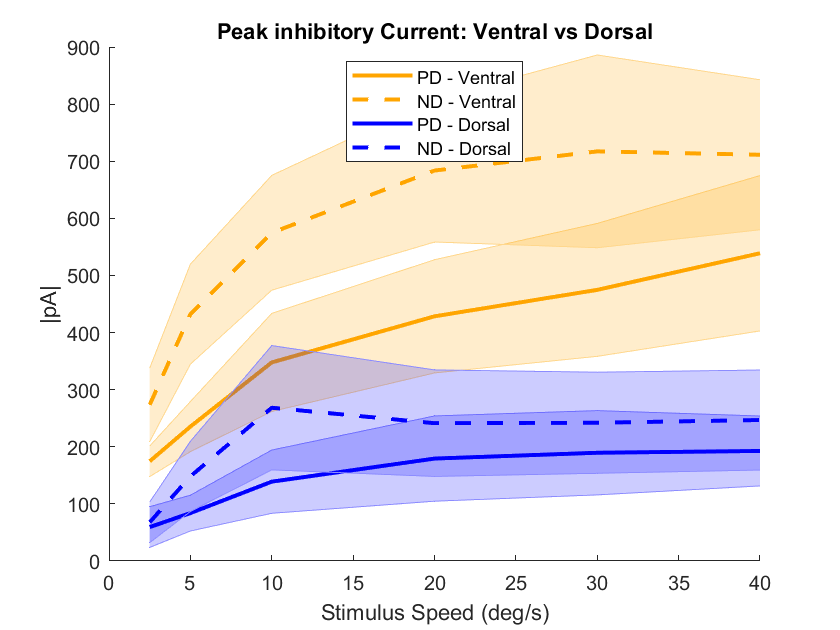

ventralIndices = coordinates(:, 2) < 0;
dorsalIndices = coordinates(:, 2) > 0;
nasalIndices = coordinates(:, 1) < 0;
temporalIndices = coordinates(:, 1) > 0;

SE_F = @(m) std(m)/sqrt(size(m, 1));

%plot speed tuning of ventral vs dorsal cells
figure
title('Peak inhibitory Current: Ventral vs Dorsal')
hold on
shadedErrorBar(speeds, mean(peaksPD_inh(ventralIndices, :)), SE_F(peaksPD_inh(ventralIndices, :)),'lineprops', {'Color', [255, 165, 0]/255, 'LineWidth', 2})
shadedErrorBar(speeds, mean(peaksND_inh(ventralIndices, :)), SE_F(peaksND_inh(ventralIndices, :)), 'lineprops', {'Color', [255, 165, 0]/255, 'LineWidth', 2, 'LineStyle', '--'})
shadedErrorBar(speeds, mean(peaksPD_inh(dorsalIndices, :)), SE_F(peaksPD_inh(dorsalIndices, :)), 'lineprops', {'Color', [0, 0, 255]/255, 'LineWidth', 2})
shadedErrorBar(speeds, mean(peaksND_inh(dorsalIndices, :)), SE_F(peaksND_inh(dorsalIndices, :)), 'lineprops', {'Color', [0, 0, 255]/255, 'LineWidth', 2, 'LineStyle', '--'})
xlabel('Stimulus Speed (deg/s)')
ylabel('|pA|')
lgd = legend('PD - Ventral', 'ND - Ventral', 'PD - Dorsal', 'ND - Dorsal');
lgd.Location = 'best';

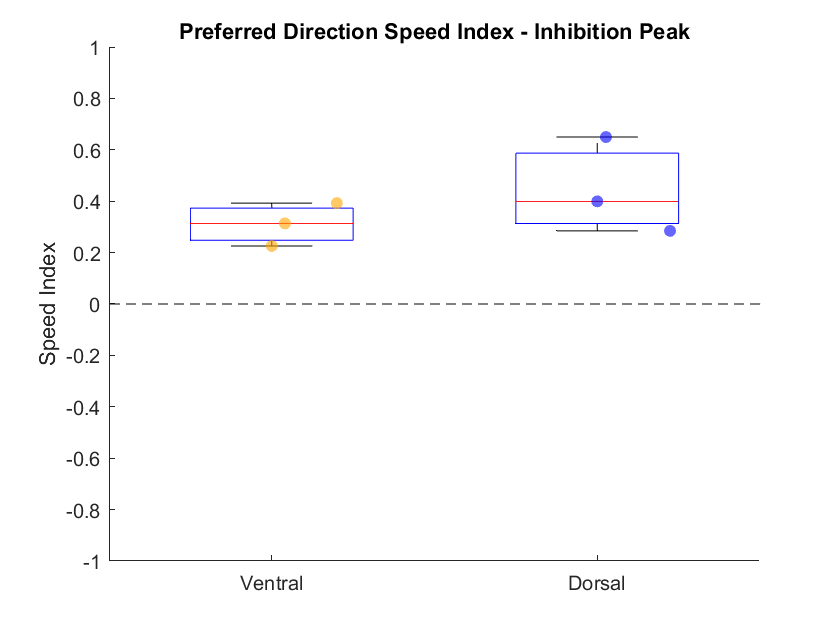

speedIndex_peak = speedIndex_F(peaksPD_inh(:, 3), peaksPD_inh(:, 1));

speedIndexPD_ventral = speedIndex_peak(ventralIndices);
speedIndexPD_dorsal = speedIndex_peak(dorsalIndices);

allPoints = [speedIndexPD_ventral; speedIndexPD_dorsal];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(speedIndexPD_ventral); 
groupIDs(indx1 + 1:end) = 1;

figure
title ('Preferred Direction Speed Index - Inhibition Peak')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(speedIndexPD_ventral)), speedIndexPD_ventral,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(speedIndexPD_dorsal))+1, speedIndexPD_dorsal,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
plot([0 3], [0 0], '--k')
xticklabels({'Ventral', 'Dorsal'})
ylabel('Speed Index')
box off
ylim([-1 1])

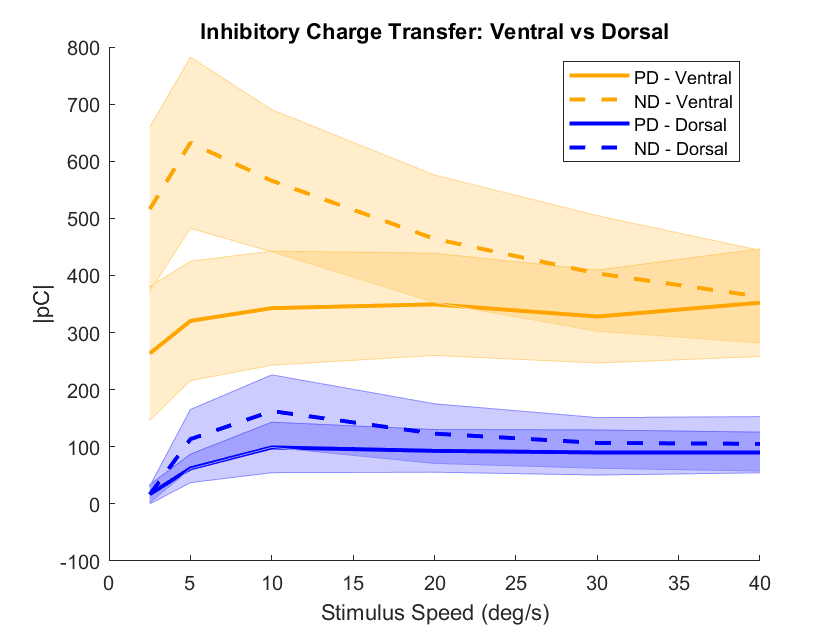


figure
title('Inhibitory Charge Transfer: Ventral vs Dorsal')
hold on
shadedErrorBar(speeds, mean(chargesPD_inh(ventralIndices, :)), SE_F(chargesPD_inh(ventralIndices, :)),'lineprops', {'Color', [255, 165, 0]/255, 'LineWidth', 2})
shadedErrorBar(speeds, mean(chargesND_inh(ventralIndices, :)), SE_F(chargesND_inh(ventralIndices, :)), 'lineprops', {'Color', [255, 165, 0]/255, 'LineWidth', 2, 'LineStyle', '--'})
shadedErrorBar(speeds, mean(chargesPD_inh(dorsalIndices, :)), SE_F(chargesPD_inh(dorsalIndices, :)), 'lineprops', {'Color', [0, 0, 255]/255, 'LineWidth', 2})
shadedErrorBar(speeds, mean(chargesND_inh(dorsalIndices, :)), SE_F(chargesND_inh(dorsalIndices, :)), 'lineprops', {'Color', [0, 0, 255]/255, 'LineWidth', 2, 'LineStyle', '--'})
xlabel('Stimulus Speed (deg/s)')
ylabel('|pC|')
lgd = legend('PD - Ventral', 'ND - Ventral', 'PD - Dorsal', 'ND - Dorsal');
lgd.Location = 'best';

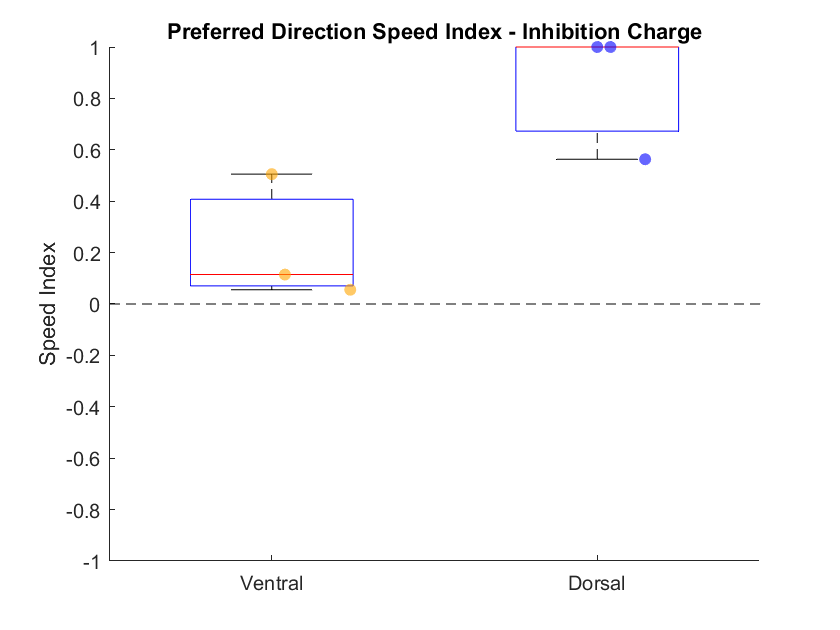

speedIndex_charge = speedIndex_F(chargesPD_inh(:, 3), chargesPD_inh(:, 1));

speedIndexPD_ventral = speedIndex_charge(ventralIndices);
speedIndexPD_dorsal = speedIndex_charge(dorsalIndices);

allPoints = [speedIndexPD_ventral; speedIndexPD_dorsal];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(speedIndexPD_ventral); 
groupIDs(indx1 + 1:end) = 1;

figure
title ('Preferred Direction Speed Index - Inhibition Charge')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(speedIndexPD_ventral)), speedIndexPD_ventral,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(speedIndexPD_dorsal))+1, speedIndexPD_dorsal,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
plot([0 3], [0 0], '--k')
xticklabels({'Ventral', 'Dorsal'})
ylabel('Speed Index')
box off
ylim([-1 inf])

## E/I

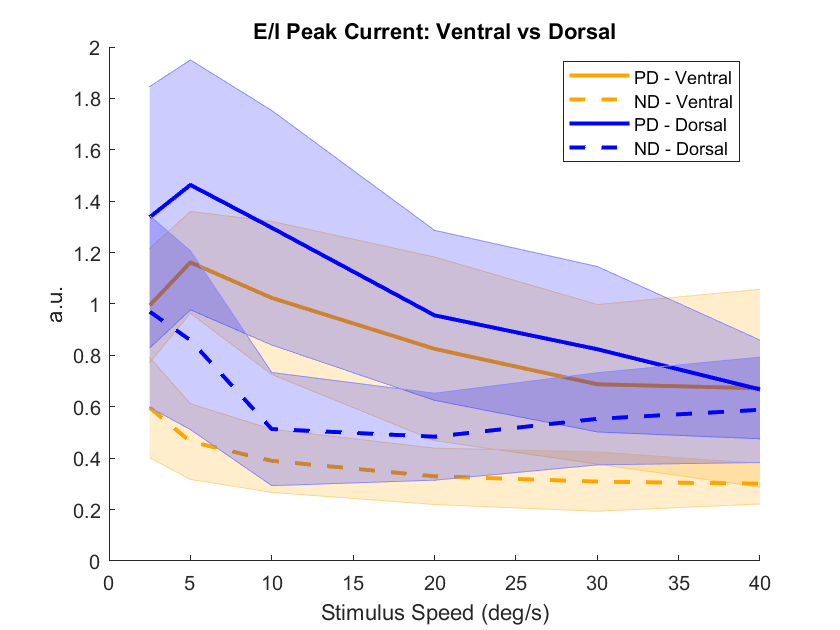

ei_peakPD = peaksPD_ex./peaksPD_inh;
ei_peakND = peaksND_ex./peaksND_inh;
ei_chargePD = chargesPD_ex./chargesPD_inh;
ei_chargeND = chargesND_ex./chargesND_inh;

ei_chargePD(ei_chargePD<0) = 0; %get rid of negatives if they exist... they mess everything up
ei_chargeND(ei_chargeND<0) = 0;

SE_F = @(m) std(m)/sqrt(size(m, 1));

%plot speed tuning of ventral vs dorsal cells
figure
title('E/I Peak Current: Ventral vs Dorsal')
hold on
shadedErrorBar(speeds, mean(ei_peakPD(ventralIndices, :)), SE_F(ei_peakPD(ventralIndices, :)),'lineprops', {'Color', [255, 165, 0]/255, 'LineWidth', 2})
shadedErrorBar(speeds, mean(ei_peakND(ventralIndices, :)), SE_F(ei_peakND(ventralIndices, :)), 'lineprops', {'Color', [255, 165, 0]/255, 'LineWidth', 2, 'LineStyle', '--'})
shadedErrorBar(speeds, mean(ei_peakPD(dorsalIndices, :)), SE_F(ei_peakPD(dorsalIndices, :)), 'lineprops', {'Color', [0, 0, 255]/255, 'LineWidth', 2})
shadedErrorBar(speeds, mean(ei_peakND(dorsalIndices, :)), SE_F(ei_peakND(dorsalIndices, :)), 'lineprops', {'Color', [0, 0, 255]/255, 'LineWidth', 2, 'LineStyle', '--'})
xlabel('Stimulus Speed (deg/s)')
ylabel('a.u.')
lgd = legend('PD - Ventral', 'ND - Ventral', 'PD - Dorsal', 'ND - Dorsal');
lgd.Location = 'best';

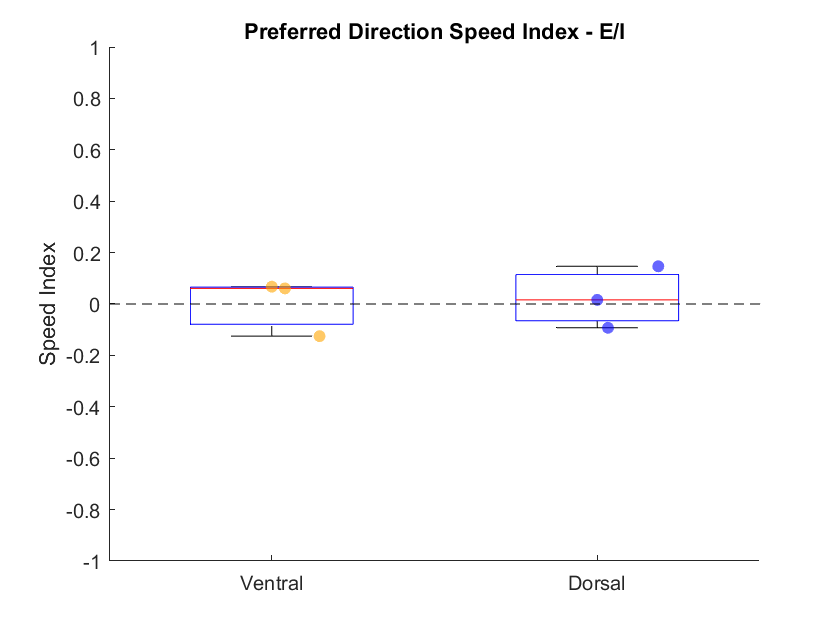


speedIndex_peak = speedIndex_F(ei_peakPD(:, 3), ei_peakPD(:, 1));

speedIndexPD_ventral = speedIndex_peak(ventralIndices);
speedIndexPD_dorsal = speedIndex_peak(dorsalIndices);

allPoints = [speedIndexPD_ventral; speedIndexPD_dorsal];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(speedIndexPD_ventral); 
groupIDs(indx1 + 1:end) = 1;

figure
title ('Preferred Direction Speed Index - E/I')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(speedIndexPD_ventral)), speedIndexPD_ventral,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(speedIndexPD_dorsal))+1, speedIndexPD_dorsal,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
plot([0 3], [0 0], '--k')
xticklabels({'Ventral', 'Dorsal'})
ylabel('Speed Index')
box off
ylim([-1 1])

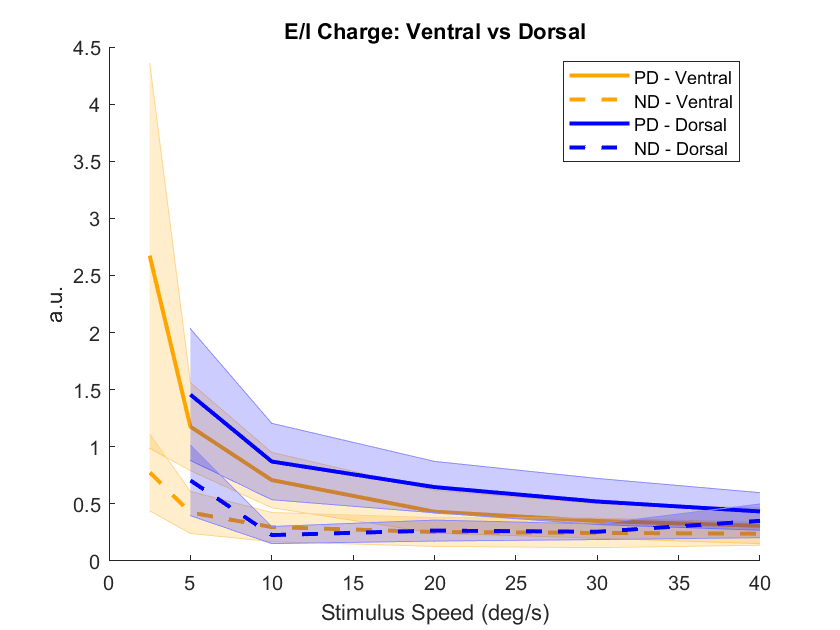


figure
title('E/I Charge: Ventral vs Dorsal')
hold on
shadedErrorBar(speeds, mean(ei_chargePD(ventralIndices, :)), SE_F(ei_chargePD(ventralIndices, :)),'lineprops', {'Color', [255, 165, 0]/255, 'LineWidth', 2})
shadedErrorBar(speeds, mean(ei_chargeND(ventralIndices, :)), SE_F(ei_chargeND(ventralIndices, :)), 'lineprops', {'Color', [255, 165, 0]/255, 'LineWidth', 2, 'LineStyle', '--'})
shadedErrorBar(speeds, mean(ei_chargePD(dorsalIndices, :)), SE_F(ei_chargePD(dorsalIndices, :)), 'lineprops', {'Color', [0, 0, 255]/255, 'LineWidth', 2})
shadedErrorBar(speeds, mean(ei_chargeND(dorsalIndices, :)), SE_F(ei_chargeND(dorsalIndices, :)), 'lineprops', {'Color', [0, 0, 255]/255, 'LineWidth', 2, 'LineStyle', '--'})
xlabel('Stimulus Speed (deg/s)')
ylabel('a.u.')
lgd = legend('PD - Ventral', 'ND - Ventral', 'PD - Dorsal', 'ND - Dorsal');
lgd.Location = 'best';

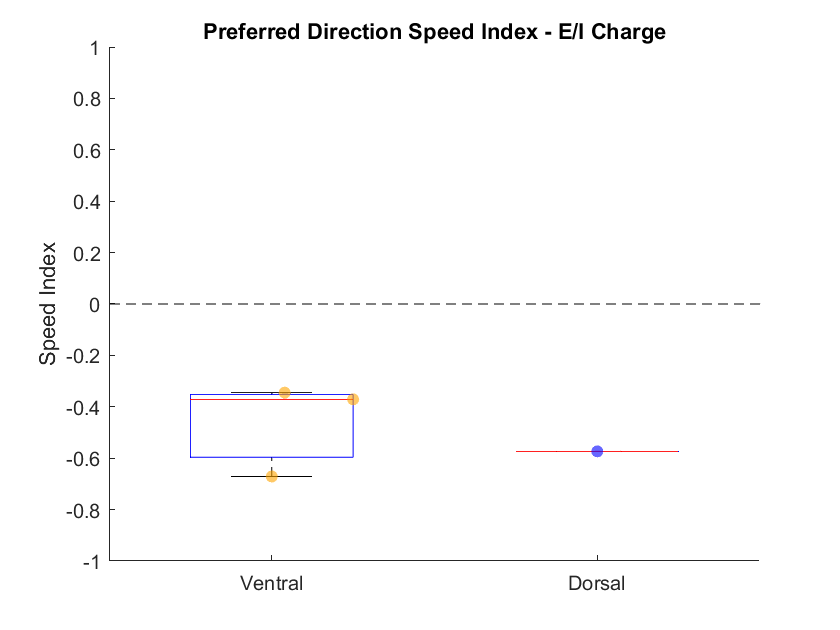

ei_chargePD(ei_chargePD<0) = 0; %get rid of negatives if they exist... they mess everything up

speedIndex_charge = speedIndex_F(ei_chargePD(:, 3), ei_chargePD(:, 1));

speedIndexPD_ventral = speedIndex_charge(ventralIndices);
speedIndexPD_dorsal = speedIndex_charge(dorsalIndices);

allPoints = [speedIndexPD_ventral; speedIndexPD_dorsal];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(speedIndexPD_ventral); 
groupIDs(indx1 + 1:end) = 1;

figure
title ('Preferred Direction Speed Index - E/I Charge')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(speedIndexPD_ventral)), speedIndexPD_ventral,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(speedIndexPD_dorsal))+1, speedIndexPD_dorsal,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
plot([0 3], [0 0], '--k')
xticklabels({'Ventral', 'Dorsal'})
ylabel('Speed Index')
box off
ylim([-1 1])